%%% Reference
insize = 16; % input file dimensions - output: insize / pool
VproOutStride = 0;
pool = 1;    % 2 = perform with size 2, 1 = off
leak = 0;    % 1 = on, 0 = off
kernel_size = 3;
ics = 1; % 3
ocs = 1;% 16
%kernel = int16([-1  0  1; -2  0  2; -1  0  1])
%kernel = int16([-1  -2  -1; 0  0  0; 1  2  1])

%kernels[x,y, ic, oc]

%kernels(:,:,1,1) = [-9368 -26847 -18397; -3540   2786  12244; 11015  25604   9434];
%kernels(:,:,2,1) = [ -4984 -23017 -14314; -4372   2802  11455;  7478  20249   3399];
%kernels(:,:,1,2) = [ -1 -2 -1; 0 0 0; 1  2  1 ];
%kernels(:,:,2,2) = [ -1 -2 -1; 0 0 0; 1  2  1 ];

kernels = zeros(kernel_size,kernel_size,ics,ocs);
%kernels(1,1,1,1) = 1;
%kernels(1,1,2,1) = 2;
%kernels(1,1,1,2) = 3;
%kernels(1,1,2,2) = 4;
%kernels(1,1,1,3) = 5;
%kernels(1,1,2,3) = 6;
kernels(:,:,1,1) = [ 0 0 0; 0 1 0; 0 0 0 ];
kernels(:,:,2,1) = [ 0 0 0; 0 1 0; 0 0 0 ];
% kernels(:,:,1,2) = [ 0 0 0; 0 1 0; 0 0 0 ];
% kernels(:,:,2,2) = [ 0 0 0; 0 1 0; 0 0 0 ];
% kernels(:,:,1,3) = [ 0 0 0; 0 1 0; 0 0 0 ];
% kernels(:,:,2,3) = [ 0 0 0; 0 1 0; 0 0 0 ];
%kernels(:,:,1,1) = [ -9368 -26847 -18397;  -3540   2786  12244;  11015  25604   9434];
%kernels(:,:,2,1) = [ -5995 -22729 -15188;  -4632   3718  12504;   6750  19607   6315];
%kernels(:,:,1,2) = [  -205   4590   4678;    -97   5375   4365;  -1509   2392   1628];
%kernels(:,:,2,2) = [ -8792  -7784  -8303; -11884 -11903  -9917; -10579  -9237  -8544];
%kernels(:,:,1,3) = [  5412  10965   5169;  14022  20025   8693;   8654  12477   2983];
%kernels(:,:,2,3) = [ -2980  -4784    176;  -6973  -9096   -342;  -2414  -4820   4982];
%kernels(:,:,1,1) = [-2342 -6711 -4599;  -885   696  3061;  2753  6401  2358];
%kernels(:,:,2,1) = [-1498 -5682 -3797; -1158   929  3126;  1687  4901  1578];
%kernels(:,:,1,2) = [  -51  1147  1169;   -24  1343  1091;  -377   598   407];
%kernels(:,:,2,2) = [-2198 -1946 -2075; -2971 -2975 -2479; -2644 -2309 -2136];
%kernels(:,:,1,3) = [ 1353  2741  1292;  3505  5006  2173;  2163  3119   745];
%kernels(:,:,2,3) = [ -745 -1196    44; -1743 -2274   -85;  -603 -1205  1245];
k2 =   [[[-2342 -6711 -4599;  -885   696  3061;  2753  6401  2358];
   [  -51  1147  1169;   -24  1343  1091;  -377   598   407];
   [ 1353  2741  1292;  3505  5006  2173;  2163  3119   745];
   [ 2074  4422  2844; -1334  1073  2429; -3864 -4910 -1815];
   [-1919 -1367 -2076; -2340 -3402 -2059; -2401 -3270 -1771];
   [-3781  1172  3227; -5041  1876  3366; -3973  1571  2859];
   [    0 -2600 -2014;  3162  -530 -3132;  2415  3050   216];
   [  -46  -108  1762; -1369  -758   989; -1273  -859   516];
   [ -222   280  -241;  -605  -567  -604;  -618   146  -399];
   [ -899  4910 -4178; -2809  6757 -3867; -2694  4515 -1882];
   [ -830 -1692 -1383; -1570 -2458 -2197; -1768 -2064 -1565];
   [ -184  -329  -184;    -2  -518  -244;  -525  -643  -499];
   [  -46  1997   -89;   496  1829   968;  -339    10 -1604];
   [ 2285  3069 -2165;  4502  1129 -5062;  3233 -2262 -3483];
   [  658 -3199  2502;  -387 -4458  4915; -2210   834  1261];
   [ -347 -2153   144;  -438 -3180 -1582;  1080 -1061  -117]];
  [[-1246 -5754 -3578; -1093   700  2863;  1869  5062   849];
   [ 1636  1941  1582;  1816  2004  1761;  1592  1949  1810];
   [ -379  -895 -1101; -1427 -2433 -2259; -1648 -2122 -2127];
   [ 1319  3368  2200;  -983   906  2266; -2923 -4615 -1959];
   [  108  2165  1646;  1153   387  1407;   764   761  1926];
   [-3707   787  2479; -4929  1816  2931; -3066  1187  1869];
   [  514 -2252 -1946;  2839   167 -3248;  1789  2897   149];
   [-1068  -287  1371; -1324  -795  1172; -1590  -517  1042];
   [ -205  -150    55;  -556  -471   -62;  -309  -267  -465];
   [ -959  4711 -4039; -2774  6520 -3524; -2771  3960 -1398];
   [ -638 -1286 -1542; -1543 -1994 -1922; -1157 -1791 -1655];
   [   39  -621   -44;  -649  -188  -628;  -731  -532  -343];
   [  173  1915    93;   267  2445  1003;  -912    20 -1745];
   [ 1862  2444 -2634;  3733   679 -4945;  2677 -1942 -2543];
   [ 1562 -2918  1663;   679 -4460  3929; -1528   904   596];
   [ -192 -1462  -297;  -122 -2591 -1077;   776  -800    74]];
  [[-1498 -5682 -3797; -1158   929  3126;  1687  4901  1578];
   [-2198 -1946 -2075; -2971 -2975 -2479; -2644 -2309 -2136];
   [ -745 -1196    44; -1743 -2274   -85;  -603 -1205  1245];
   [ 1550  2868  1472;  -925   832  1612; -2911 -3774 -1575];
   [  229  2835   274;  2558  2936  -124;  1820  1980   106];
   [-2688   530  1155; -3837  1539  1761; -2449  1461  1539];
   [ -379 -2951 -2211;  2800   -99 -2993;  2031  2663   239];
   [  320   926   699;   567  1082  1429;  1056  1557  1727];
   [ -490  -258    33;  -613  -538  -200;  -484  -560  -421];
   [ -525  2932 -2572; -1924  4437 -2283; -1806  2236  -588];
   [ -787 -1819 -1714; -1517 -1837 -1816; -1591 -1918 -1499];
   [ -201  -395  -126;  -439    29  -387;  -368  -507    62];
   [ -131  1688     1;    71  1588   448; -1406  -100 -2051];
   [ 1750  2248 -2227;  3248   879 -4267;  2240 -1970 -2596];
   [ 1058 -2692  1074;     0 -3810  3236; -1733  1161   486];
   [ -645 -2043  -296;  -813 -2526 -1229;  -605 -1349  -665]]];

for ic=1:ics
    for oc=1:ocs
        index = ((ic-1)*ocs+(oc-1));
        % copy 3 elements
        
        
%         kernels(:,:,ic, oc) = k2(index*kernel_size+1:index*kernel_size+kernel_size,:);
    end
end

kernels = int16(kernels);
size(kernels)

ans =      3     3     2



% for all oc
% bias = int16([347,  453,  283,  412,  777,  635,  281, -1771, -109,  -13, 4161,  -53,-2950,  505, 360, 4929])
% bias= int16([ 0, 0, 0]);
bias = int16([347,  453,  283]);

conv_result_shift_right = 1; % 7
bias_store_shift_right = 1;  % 8
bias_load_shift_right = -1;  % -5

% all ic
%fileID = fopen('input_test_lena_revEnd.bin','r');
%fileID1 = fopen('input0_revEnd.bin','r');
%fileID2 = fopen('input1_revEnd.bin','r');
%fileID1 = fopen('inputsmall0_revEnd.bin','r');
%fileID2 = fopen('inputsmall1_revEnd.bin','r');
%fileID1 = fopen('inputmedium0_revEnd.bin','r');
%fileID2 = fopen('inputmedium1_revEnd.bin','r');
%fileID1 = fopen('inputfinal0_revEnd.bin','r');
%fileID2 = fopen('inputfinal1_revEnd.bin','r');
%infiles = ['input0_random_gen.bin'; 'input1_random_gen.bin'; 'input2_random_gen.bin'];
%infiles = ['input0_revEnd.bin'; 'input1_revEnd.bin'; 'input2_revEnd.bin'];
infiles = ['results/input/channel_0.bin'; 'results/input/channel_1.bin'; 'results/input/channel_2.bin'];

Bs  = zeros(insize, insize, ics);
for ic = 1:ics
    fileID1 = fopen(infiles(ic,:),'r');
    A = uint16(fread(fileID1,[insize insize],'uint16'));
    A = uint16(swapbytes(A'));
    Bs(:,:,ic) = typecastarray(A, 'int16');
    %max(max(Bs, [],'omitnan'))
    %min(min(Bs, [],'omitnan'))
end

if max(max(max(Bs))) > 2^15 - 1 || min(min(min(Bs))) < -2^15
    "OVERFLOW! Input as 16-bit..."
    "" + min(min(min(Bs))) +  " - " + max(max(max(Bs)))
else
    "Input ok " + min(min(min(Bs))) +  " - " + max(max(max(Bs)))
end

ans = "Input ok 746 - 3799"


%%% CONV + BIAS
C = int32(zeros(insize, insize, ocs));
for oc = 1:ocs
    for ic = 1:ics
        if (ic == 1)
            C2  = convolve(Bs(:,:,ic), kernels(:,:,ic, oc), bias(oc), conv_result_shift_right, bias_load_shift_right);
        else % dont add bias
            C2  = convolve(Bs(:,:,ic), kernels(:,:,ic, oc), 0, conv_result_shift_right, bias_load_shift_right);
        end
        C(:,:,oc) = C(:,:,oc) + C2;
    end
end

if max(max(max(C))) > 2^23 - 1 || min(min(min(C))) < -2^23
    "OVERFLOW! CONV Result in 24-bit..."
    "" + min(min(min(C))) +  " - " + max(max(max(C)))
    error("CONV Overflow!")
else
    "Conv ok " + min(min(min(C))) +  " - " + max(max(max(C)))
end

ans = "Conv ok 1067 - 2594"


%%% POOLING
if pool == 2
    Cpool = int32(zeros(insize/pool, insize/pool, ocs));
    for oc = 1:ocs
        Cpool(:,:,oc) = maxpool2(C(:,:,oc));
    end
C = Cpool;
end
%%% LEAKY RELU
if leak == 1
    for oc = 1:ocs
        mask = C(:,:,oc)<0;
        Cleak = int64(C(:,:,oc));
        %Cleak(mask) = Cleak(mask) .* 0.1;
        Cleak(mask) = Cleak(mask) .* 26214;
        Cleak(mask) = Cleak(mask) ./ (2^18);
        C(:,:,oc) = int32(Cleak(:,:));
    end
end
%%% Store
C = C ./ 2^bias_store_shift_right;
Coverflowfix = int16(C);
if max(max(max(C))) > 2^15 - 1 || min(min(min(C))) < -2^15
    "OVERFLOW! Store as 16-bit..."
    "" + min(min(min(C))) +  " - " + max(max(max(C))) + " cut to " + min(min(min(Coverflowfix))) +  " - " + max(max(max(Coverflowfix)))
    %&error("STORE Overflow!")
else
    "Store ok " + min(min(min(C))) +  " - " + max(max(max(C)))
end

ans = "Store ok 534 - 1297"

C = Coverflowfix;

"Matlab Reference Result"

ans = "Matlab Reference Result"

max(max(max(C, [],'omitnan')))

ans = int16
1297

min(min(min(C, [],'omitnan')))

ans = int16
534

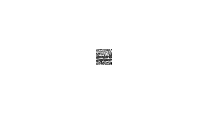

for oc = 1:ocs
    subplot(1,ocs,oc), imshow(mat2gray(C(:,:,oc)))
end

%%% Read VPRO
% all oc
vprofile = {};
for oc=1:ocs
    file = strcat('./results/layer_0/channel_',int2str(oc-1),'.bin');
    vprofile(end+1) = {file};
end
%vprofile = [
%    './result/layer_0/channel_'+oc+'.bin'; 
%    './result/layer_0/channel_1.bin'; 
%    './result/layer_0/channel_2.bin'
%    ];

V = int16(zeros(insize/pool + VproOutStride, insize/pool + VproOutStride, ocs));
for oc = 1:ocs
    vproresultfile = fopen(cell2mat(vprofile(oc)),'r');
    V(:,:,oc) = int16(fread(vproresultfile,[insize/pool + VproOutStride insize/pool + VproOutStride],'int16'));
    V(:,:,oc) = swapbytes(V(:,:,oc)');
end
V = V(1:insize/pool, 1:insize/pool, :);

"VPRO Result"

ans = "VPRO Result"

max(max(max(V , [],'omitnan')))

ans = int16
1296

min(min(min(V , [],'omitnan')))

ans = int16
533

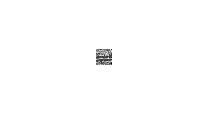

for oc = 1:ocs
    subplot(1,ocs,oc), imshow(mat2gray(V(:,:,oc)))
end


"Compare of VPRO Result to Matlab Reference"

ans = "Compare of VPRO Result to Matlab Reference"

diff = V - C;
max(max(max(abs(diff))))

ans = int16
1

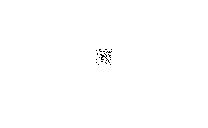

for oc = 1:ocs
    subplot(1,ocs,oc), imshow(mat2gray(abs(diff(:,:,oc))))

    %subplot(2,ocs,oc*2), imshow(mat2gray(diff(:,:,oc)))
    %subplot(2,ocs,oc*2+1), imshow(mat2gray(diffFPGA(:,:,oc)))
end

%%% Read C Ref (Sim) + Compare 
%
% cfile = {};
% for oc=1:ocs
%     file = strcat('/home/gesper/repositories/CORE_VPRO/sw/vpro/cnn_yolo_lite_sim/data/reference_c/binary/Layer_1/channel_',int2str(oc-1),'.bin');
%     cfile(end+1) = {file};
% end
% Vc = int16(zeros(insize/pool, insize/pool, ocs));
% 
% for oc = 1:ocs
%     cres = fopen(cell2mat(cfile(oc)),'r');
%     Vc(:,:,oc) = int16(fread(cres,[insize/pool insize/pool],'int16'));
%     Vc(:,:,oc) = swapbytes(Vc(:,:,oc)');
% end
% 
% "Compare of C-Code (Sim) to Matlab Reference"
% diffC = Vc - C;
% max(max(max(abs(diffC))))
% for oc = 1:ocs
%     subplot(1,ocs,oc), imshow(mat2gray(abs(diffC(:,:,oc))))
% end

"Unterschiede zwischen Sim (VPRO) und Matlab Reference:" 

ans = "Unterschiede zwischen Sim (VPRO) und Matlab Reference:"

max(max(max(abs(Vc - C))))

Unrecognized function or variable 'Vc'.

%"Unterschiede zwischen Sim (VPRO) und HWSim (VPRO):" 
%max(max(max(abs(Vc-V))))

function C = convolve(in, kernel, bias, conv_result_shift_right, bias_load_shift_right)
    %C = int16(conv2(B,kernel','same'));
    pw = (size(kernel, 1)-1)/2;
    C = padarray(in, [pw pw], 0, 'both');
    D = int32(zeros(size(in,1) + size(kernel,1) - 1, size(in,2) + size(kernel,2) - 1));
    D = D + (int32(bias)*(2^(-bias_load_shift_right+conv_result_shift_right)));
    for ii = 1:size(in,1)
        for jj = 1:size(in,2)
            D(ii,jj) = D(ii, jj) + sum(sum( ...
                int32(kernel).*int32(C(ii:ii+size(kernel,1)-1, jj:jj+size(kernel,2)-1))));
        end
    end
    C = D(1:size(in,1),1:size(in,2));
    C = int32(C ./ 2^conv_result_shift_right);
end

function D = maxpool2(in)
    D = zeros(size(in,1)/2, size(in,2)/2);
    for ii = 1:2:size(in,1)
        for jj = 1:2:size(in,2)
            D((ii+1)/2,(jj+1)/2) = max([in(ii, jj) in(ii, jj+1) in(ii+1, jj) in(ii+1, jj+1)]);
        end
    end
end

function NewArray = typecastarray(TheArray, NewType)
  curshape = num2cell(size(TheArray));
  NewArray = reshape( typecast(TheArray(:),NewType), [], curshape{2:end});
end
